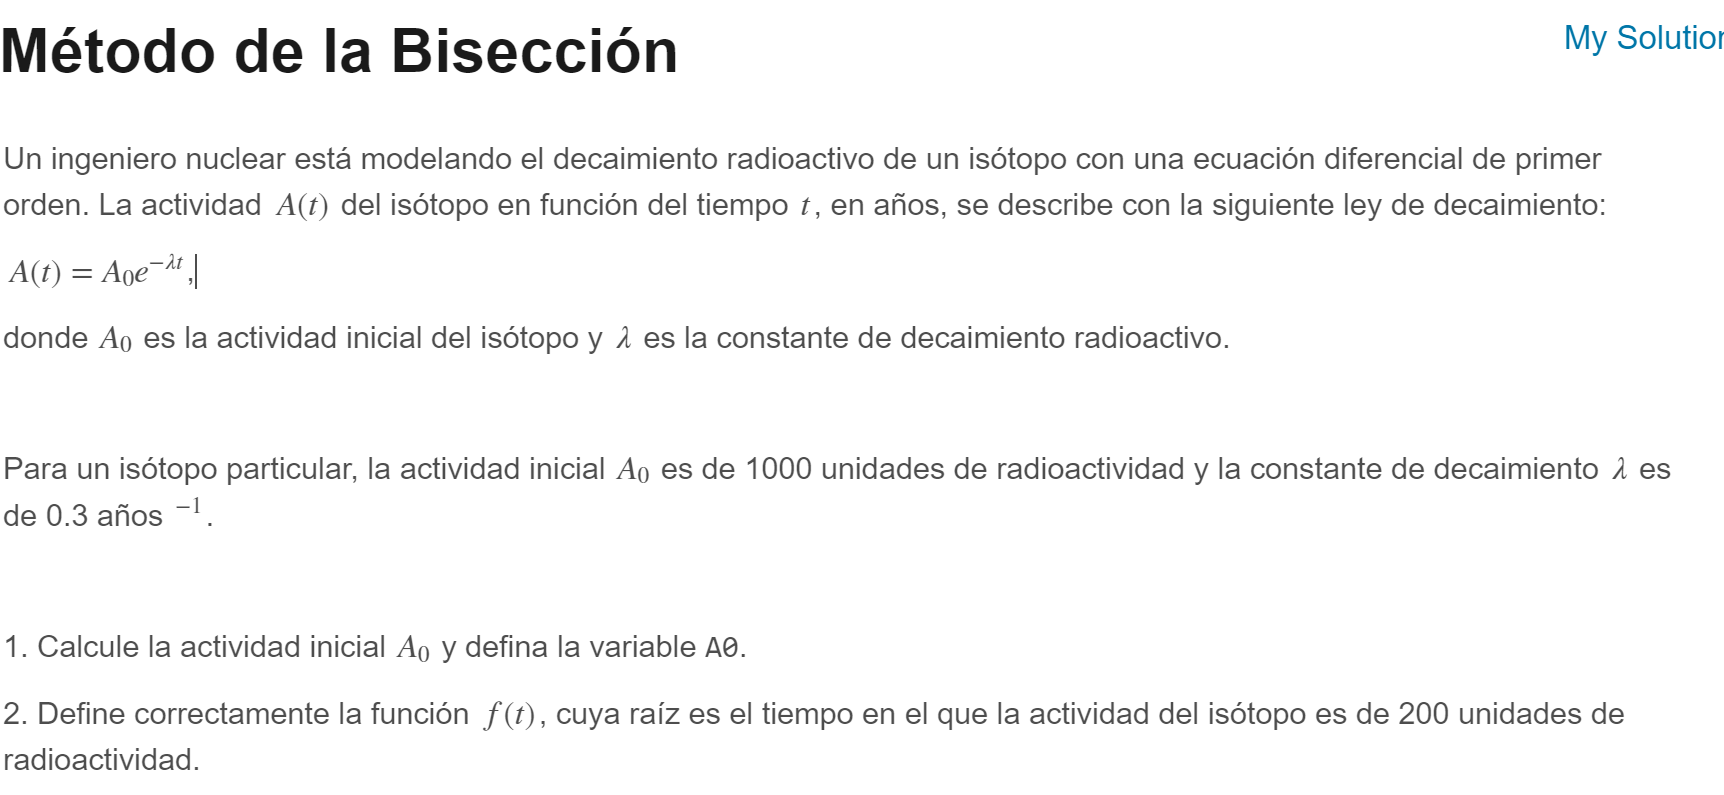

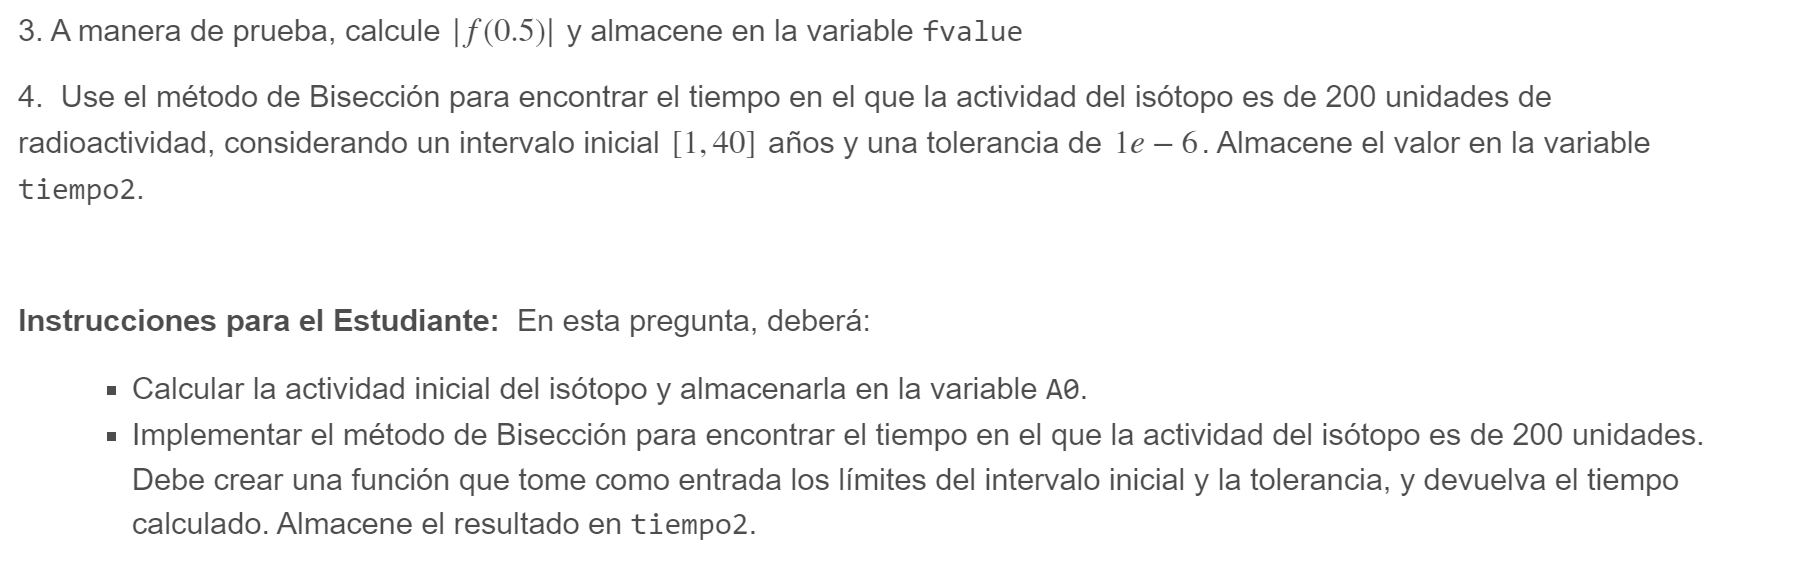

format long
A0 = 1000; % unidades de radioactividad
lambda = 0.3; % constante de decaimiento
% función a encontrar la raíz
f = @(t) A0 * exp( -lambda*t) - 200;
fvalue=abs(f(0.5));
tiempo2 = biseccion(f,1, 40, 1e-6); % calcular el tiempo con actividad de 200 unidades


function t_200 = biseccion(f,a, b, x)
  c = (a + b)/2;
  error = 1;

  while error>x

      if(f(a)*f(c) < 0)
          b = c;
      else
          a = c;
      end

      error = b-a;
      c = (a + b) / 2;
    
  end

  t_200 = c;

end
